# Compute Minimum Snap Trajectory for 2-D Planar Motion

Use the `minsnappolytraj` function with a given set of 2-D *xy* waypoints. Time points for the waypoints are also given.

wpts = [1 4 4 3 -2 0; 0 1 2 4 3 1];
tpts = 0:5;

Specify the number of samples in the output trajectory.

numsamples = 50;

Compute minimum snap trajectories. The function outputs the trajectory positions (`q`), velocity (`qd`), acceleration (`qdd`), jerks (`qddd`), and snaps (`qdddd`) at the given number of samples.

[q,qd,qdd,qddd,qdddd,pp,timepoints,tsamples] = minsnappolytraj(wpts,tpts,numsamples);

Plot the trajectories for the *x- *and *y*-positions. Compare the trajectory with each waypoint.

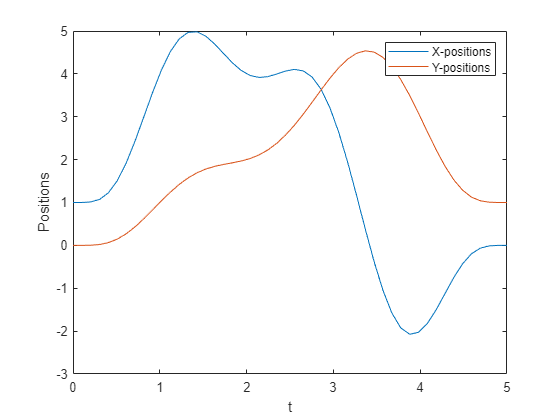

plot(tsamples,q)
%hold on
%plot(timepoints,wpts,'x')
xlabel('t')
ylabel('Positions')
legend('X-positions','Y-positions')

%hold off

You can also verify the actual positions in the 2-D plane. Plot the separate rows of the `q` vector and the waypoints as *x-* and *y- *positions.

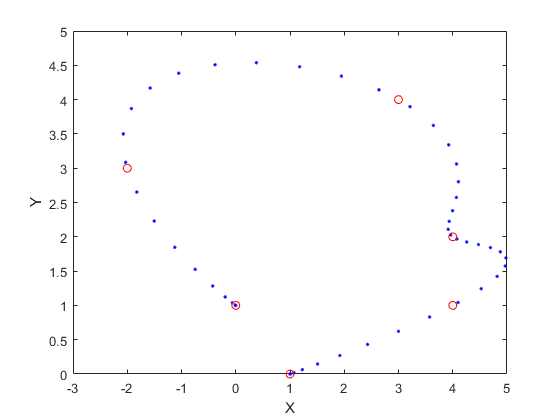

figure
plot(q(1,:),q(2,:),'.b',wpts(1,:),wpts(2,:),'or')
xlabel('X')
ylabel('Y')

*Copyright 2020 The MathWorks, Inc.*